#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# Signals

All types of medical imaging discussed in this course involve the measurement of electromagnetic waves/particles or acoustic variations --- these are *signals* -- and we process these signals to generate a image. In order to describe these signals mathematically, it is convenient to know a few common signal definitions. See Figure A.1 in Suetens_Ed2_AppendixA -- posted on Brightspace.  

clc
close all
clear all

## Delta and Step Functions

The [Dirac](https://en.wikipedia.org/wiki/Paul_Dirac) delta (aka, Impulse) and Heaviside step function are generalized functions that provide a mathematical representation for an instantaneous (in time or space) occurance or change of a signal. 

The Impulse function is particularly useful in this course. It's definition is a bit stange looking:


$$\delta(x) = \begin{cases}
    	\infty  & \ \ x = 0\\
    	0  & \ \ x \neq 0\\
  	\end{cases} \\
  	\\ \text{with the requirement,}
  	\\
  	\int_{-\infty}^\infty dx\ \delta(x) = 1.$$


From this definition, you can see that there is no simple way to visualize this function. One way to think about it is to imagine a Gaussian function,

$f(x) = \frac{1}{\sqrt{2\pi s^2}}\exp\left(\frac{-x^2}{2s^2}\right)$,

that gets narrower and narrower until it is infinitesimally narrow and infinitely high at $x=0$. Adjust the slider below from $s = 1$ (normalized Gaussian function) to something close to zero (approaching, conceptually, the delta function).

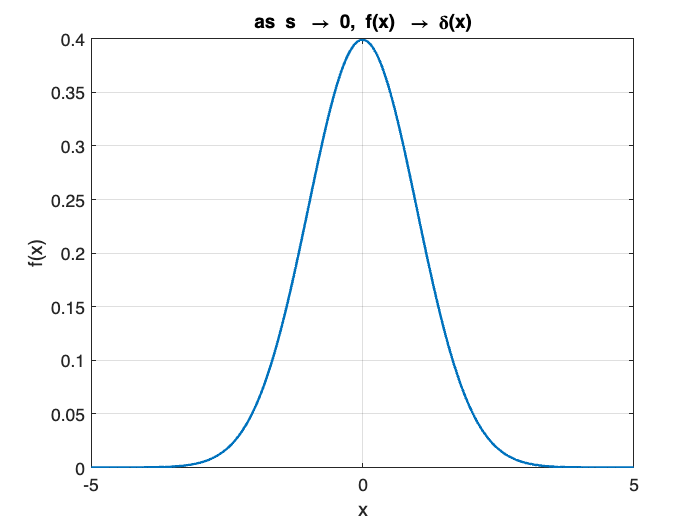

s =1;
x = linspace(-5,5,1001);
plot(x,1./sqrt(2*pi*s^2).*exp(-x.^2/(2*s^2)))
xlabel('x')
ylabel('f(x)')
title('as s \rightarrow 0, f(x) \rightarrow \delta(x)')

In the context of imaging, the detla function extends naturally to a 2D function, as 


$$\delta(x,y) = \begin{cases}
    	\infty  & \ \ (x, y) = (0.0)\\
    	0  & \ \ \text{otherwise}\\
  	\end{cases} \\
  	\\ \text{with the requirement,}
  	\\
  	\int_{-\infty}^\infty \int_{-\infty}^\infty dx \, dy\ \delta(x,y) = 1$$


and so forth for 3D.  

Here, think of a 2D or 3D impulse function as describing a perfect point source. If you try to image that perfect point source with your imaging systems (X-Ray, MRI, Nikon camera, whatever), then the resulting image is the *point spread function* (PSF) The PSF is a common characterization of resolution of an imaging system. More on this below/later.

The Heaviside step function (named after the famous engineer, [Oliver Heaviside](https://en.wikipedia.org/wiki/Oliver_Heaviside)) is equal to the integral of the Dirac delta function. 

MATLAB provides a discrete-time version of both the Dirac delta function and the Heaviside step function.

See 

help dirac

--- help for sym/dirac ---

 dirac  Symbolic delta function.
     dirac(X) is zero for all X, except X == 0 where it is infinite.
     dirac(X) is not a function in the strict sense, but rather a
     distribution with int(dirac(x-a)*f(x),-inf,inf) = f(a) and
     diff(heaviside(x),x) = dirac(x).
     dirac(N,X) represents the N-th derivative of dirac(X).
 
     See also sym/heaviside.

    Documentation for sym/dirac
    Other functions named dirac




help heaviside

 heaviside    Step function.
     heaviside(X) is 0 for X < 0 and 1 for X > 0.
     The value heaviside(0) is 0.5 by default. It
     can be changed to any value v by the call
     sympref('HeavisideAtOrigin', v).
 
     See also dirac.

    Documentation for heaviside
    Other functions named heaviside



Also, both `dirac` and `heaviside` are understood in continuous terms by MATLAB's symbolic processing.

E.g., 

`>> syms x`

`>> diff(heaviside(x),x)`

`ans =`

`dirac(x)`

We're not going to make much use of MATLAB's symbolic tools, but I thought that was cool.

### Sifting Property

An important use of the impulse function is known as *sifting property* which involves using an impulse function to *sift* out values from a function at particular points in time or space. 

Given a signal, $s(x)$, and the Dirac Delta function, $\delta(x)$, sifting property tells us


$$\int_{-\infty}^{\infty}dx \;\delta(x-x_0)s(x) = s(x_0)$$


This might seem unexcited here, but it will be necessary in understanding a general form relating the input and output of certain imaging systems. More on that in a bit.

Note that a rectangular function can be constructed from two heaviside functions

E.g., 

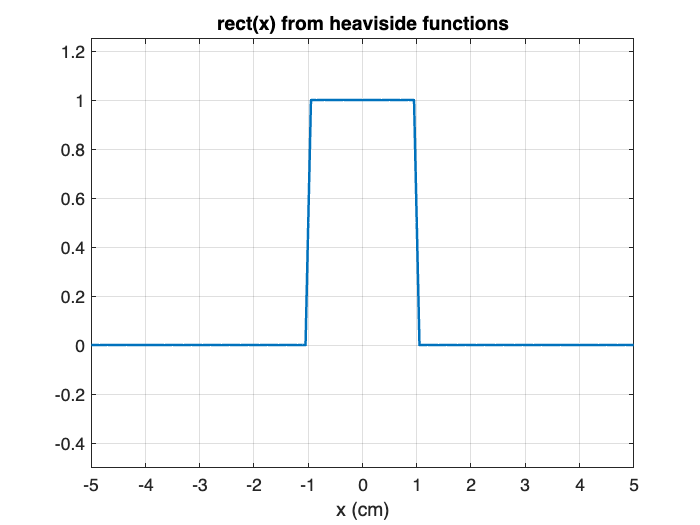

x = linspace(-5,5,201); % units of cm, for example
L = 2; % width of rect pulse, cm
rct = heaviside(-x+L/2)+heaviside(x+L/2)-1;
plot(x,rct), axis([-5 5 -0.5 1.25])
set(gca,'XTick',(-5:5))
xlabel('x (cm)'), title('rect(x) from heaviside functions')
grid on

Again, for imaging, t**he rect function has 2D and 3D formulations. In 2D,**

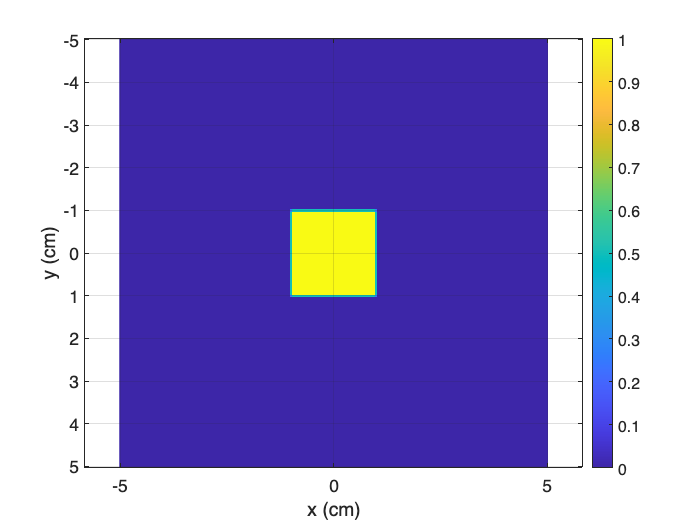

rct2 = rct'*rct;
figure
imagesc(x,x,rct2), colorbar, axis('equal')
xlabel('x (cm)')
ylabel('y (cm)')

For imaging, the rect function is useful for mathematically defining a field of view (FOV).

## Sinc Function

MATLAB's `sinc(x)`function is the "normalized" sinc function, defined as 

$\mathrm{sinc}(x) = \frac{\sin(\pi x)}{\pi x}$,

which you can see from the plot below --- note the zero-crossings occur at ±1, ±2, ±3, ... . 

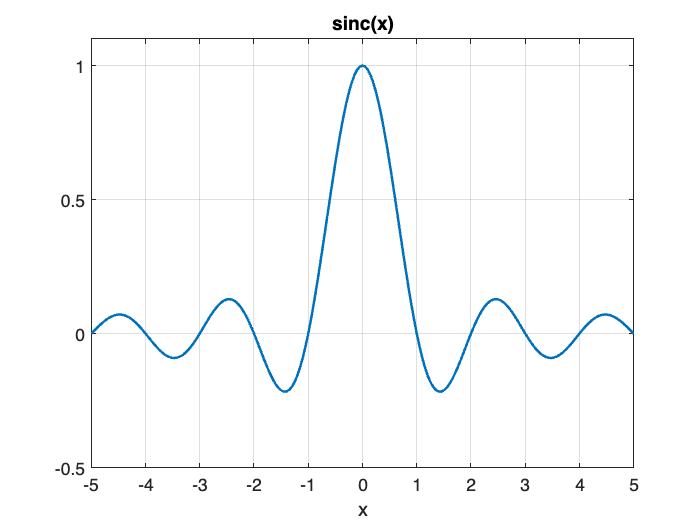

x = linspace(-5,5,201); 
plot(x,sinc(x)), axis([-5 5 -0.5 1.1])
set(gca,'XTick',(-5:5))
xlabel('x'), title('sinc(x)')
grid on

Watch out, because a sinc function can also be defined as 

$\mathrm{sinc}(x) = \frac{\sin{x}}{x}$, 

in which case the zero crossings occur at ±pi, ±2pi, ... .

The reason we care about the sinc function is because it is the Fourier Transform of the rect function. This will make more sense a little later.

## Imaginary Numbers and Complex Exponentials

To define imaginary number in MATLAB, you can use `i` or `j`, but the better choice is `1i` or `1j` to avoid confusion with common use of `i` or `j` as a index variable. Also, code with `1i` or `1j` runs a little faster that code using only `i` or `j`, because MATLAB doesn't have to figure out if you're calling the function or referring to another MATLAB object -- i.e., `1i` can only be one thing, which is the sqrt(-1).

The complex exponential function is the basis function for Fourier analysis and is easily appreciated in terms of Euler's formula


$$e^{ix} = \exp(ix) = \cos(x) + i\sin(x)$$


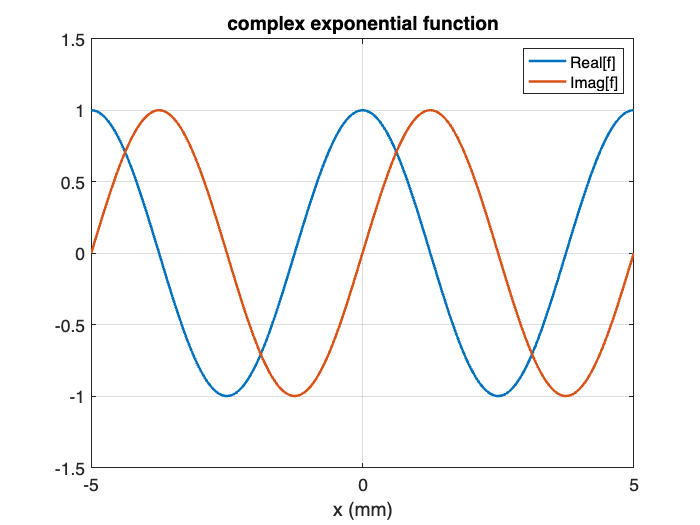

x = linspace(-5,5,201); % a spatial dimension, in mm (for example)
u0 = 0.2; % inverse units of x, mm^-1; spatial frequency

f = exp(1i*2*pi*u0*x);
plot(x,real(f),x, imag(f)), axis([-5 5 -1.5 1.5])
xlabel('x (mm)'), title('complex exponential function')
legend('Real[f]','Imag[f]')
grid on

In the complex plane, this function traces a unit circle and the frequency is the rate a parametric point moves around circle 

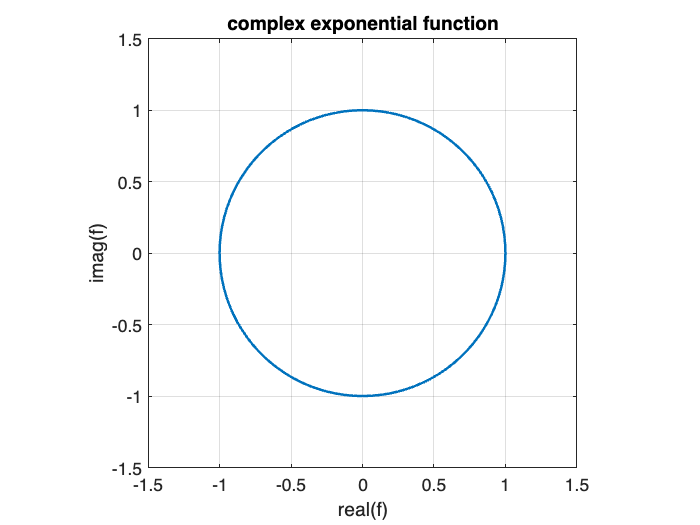

plot(f), axis([-1.5 1.5 -1.5 1.5])
xlabel('real(f)'),ylabel('imag(f)')
title('complex exponential function')
axis square
grid on